## Naloga 1

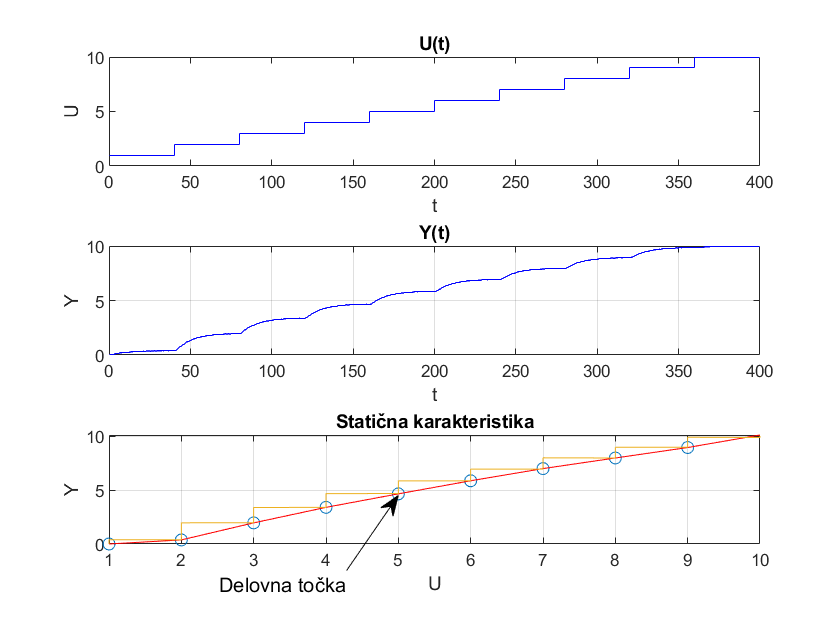

tSim = 50; % Cas simulacije
t1 = 0; % Trenutek nastopa stopnice
U0 = 0; % Zacetna vrednost stopnice
U1 = 1; % Koncna vrednost stopnice
out = sim('odziv_na_stopnico'); % Simulacija sistema
Out_ON = 10;
Out_OFF = 2;

y = Y.Data;
u = U.Data;

figure ;
subplot (3 ,1 ,1);
plot (U, 'b-'); % Izris vhoda U
xlabel ('t'); ylabel ('U'); title ('U(t)');
subplot (3 ,1 ,2);
grid on
plot (Y, 'b-'); % Izris izhoda Y
xlabel ('t'); ylabel ('Y'); title ('Y(t)');
grid on

%zapisemo tocke ustaljenih stanj in skoznje narisemo crto
subplot (3, 1, 3);
x1 = [1 2 3 4 5 6 7 8 9];
y1 = [0 0.376 1.956 3.396 4.648 5.859 6.99 7.971 8.943];

%funkcija s katero narisemo krivuljo
C = (x1(:).^(1:4))\y1(:);
xint = linspace(1,10,10)';
spl = spline(x1,y1);
plot(x1,y1,'o',xint,ppval(spl,xint),'r-')
hold on
plot(u, y);
xlabel('U'); ylabel('Y'); title('Statična karakteristika')
grid on

annotation('textarrow',[0.4125 0.4741],[0.09422 0.2135],'String','Delovna točka')


UDT = 5;
YDT = 4.648;

Torej statično karatkeristiko smo dobili tako da smo na vhod regulatorja dali enotino stopnico ter počakali da se je izhod ustalil, potem smo dodali še 9 stopnic tako da smo dobili 10 različnih vrednosti izhodov pri 10ih različnih vrednosti vhoda. Skozi točke stabilnosti sem potegnil krivuljo, kar predstavlja našo statično karakteristiko. Nekjer na sredini te krivulje smo določili delovno točko.

## Naloga 2

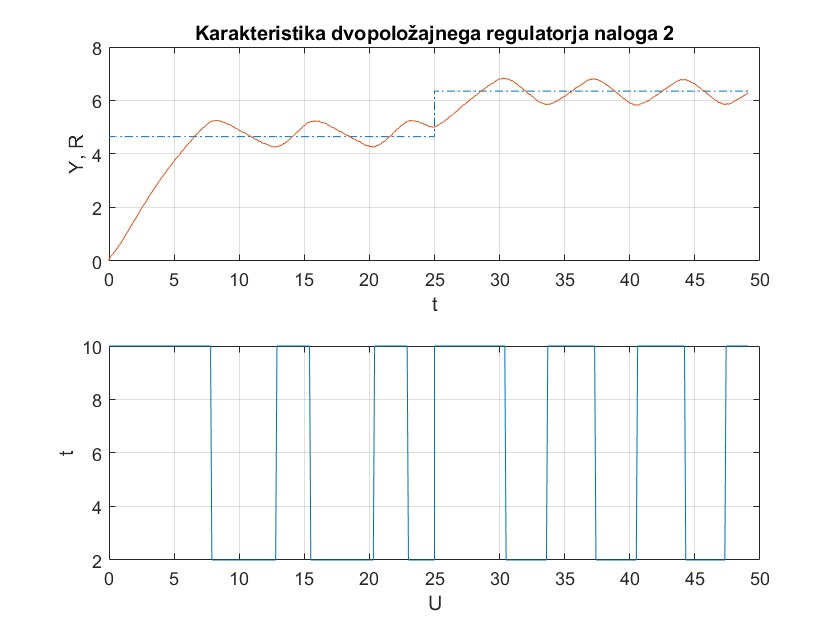

tsim= 50;
t1 = 0;
t2 = 25;
t_motnja = 0;
U_motnja = 0;
U2 = 4.648;
Out_ON = 10;
Out_OFF = 2;
epsilon = 0.6;
eps1 = epsilon/2;
eps2 = -eps1;
UDT = 5;
YDT = 4.648;

out2 = sim('regonoff');
a = length(U);
b = length(Y);
c = a-b;
U = U(1:end-c,:);
R = R(1:end-c,:);
t_sim = t_sim(1:end-c,:);

figure;
subplot(2,1,1);
plot(t_sim, R,'-.', t_sim, Y);
xlabel('t'); ylabel('Y, R'); title('Karakteristika dvopoložajnega regulatorja naloga 2');
grid on
subplot(2,1,2);
plot(t_sim, U);
xlabel('U'); ylabel('t');
grid on


epsilon = 0.6;
Ypp = 1.06;     % Obmocje spreminjanja reguliranega signala v ustaljenem stanju
tau = 7; % /s          % Perioda nihanja reguliranega signala v ustaljenem stanju

Kot podano v navodilih smo zgradili podobno shemo  - naredimo vsoto dveh stopnic z zamakom - ena nastopi potem ko se izhod ustali po prvi stopnici. Vzamemo čas trajanje simulacije tako da vedno počakamo na ustaljen izhod. Prva stopnica (referenca) sega do vrednosti izhoda delovne točke (4.648)- smo določili v prejšni nalogi, pri drugi pa nastavimo stonico s primerno ampitudo tako da je stopnica imamo lep prehod. Pri tej nalogi so predvsem važni parametri epsilon - kot neke vrste trigger pri osciloskopu, nastavil sem ga na 0.3 in -0.3 in to sta razliki od referenčne vrednosti pri katerih aktuator neha oz. začne proizvajati toploto, ter On in Off vrednosti - vrednosti izhoda. Ypp = 1.06 je peak to peak vrednost izhoda,  tau = 7 pa perioda reguliranega signala v ustaljenem stanju.

## Naloga 3

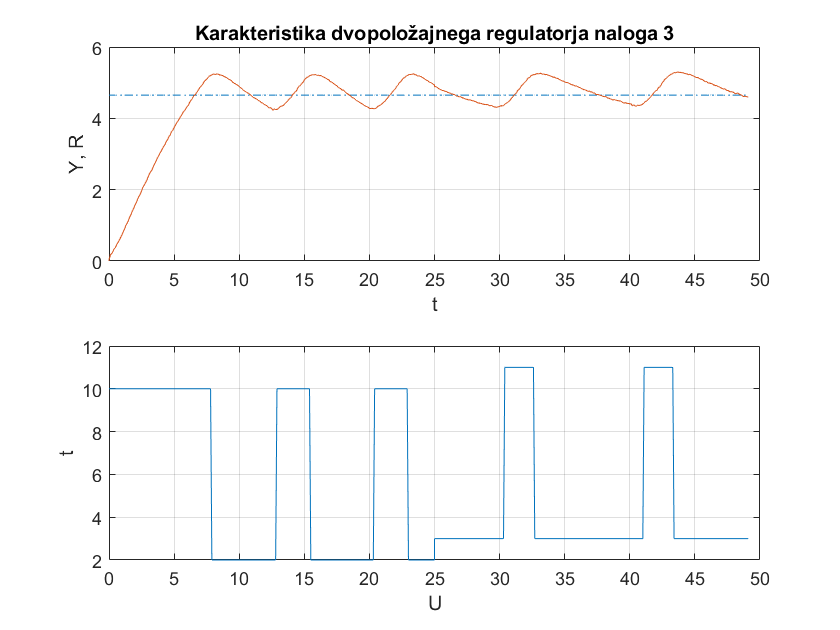

tsim = 50;
t1 = 0;
t2 = 25;
t_motnja = 25;
U_motnja = 1;
U2 = 4.648;
Out_ON = 10;
Out_OFF = 2;
epsilon = 0.6;
eps1 = epsilon/2;
eps2 = -eps1;
UDT = 5;
YDT = 4.648;

out3 = sim('regonoff1');
a = length(U);
b = length(Y);
c = a-b;
U = U(1:end-c,:);
R = R(1:end-c,:);
t_sim = t_sim(1:end-c,:);

figure;
subplot(2,1,1);
plot(t_sim, R,'-.', t_sim, Y);
xlabel('t'); ylabel('Y, R'); title('Karakteristika dvopoložajnega regulatorja naloga 3');
grid on
subplot(2,1,2);
plot(t_sim, U);
xlabel('U'); ylabel('t');
grid on

Pri tej nalogi smo dejansko le nekoliko preuredili simulinkovo datoteko, odvzeli drugo enotino stopnico iz "reference" ter jo dodali kot motnjo pred proces. Na vhodu imamo vrednost v delovni  točki, nato pa vključimo tisto motnjo - enotino stopnico, ki pa nam popestri zadeve. Torej pri tej motnji ne smemo pretoravati - saj nas lahko vrže iz linearnega območja - ko jo vključimo opazimo,da se ampakituda nič oz. zelo malo spremeni, medtem ko se frekvenca zmanjša za kakšno polovico.

Ker se nam motnja prišteva s pozitivnim predznakom, to pomeni da dobimo nekoliko hitrejše naraščanje izhoda - posledično dobimo tudi daljše padanje - kot kaže na sliki.Če bi dobili negativno motnjo - ki bi izničevala sedanjo motnjo, bi izhod bolj strmo padal in dobili bi enako karatkeristiko izhoda - originalno stanje. :)

## Naloga 4.1

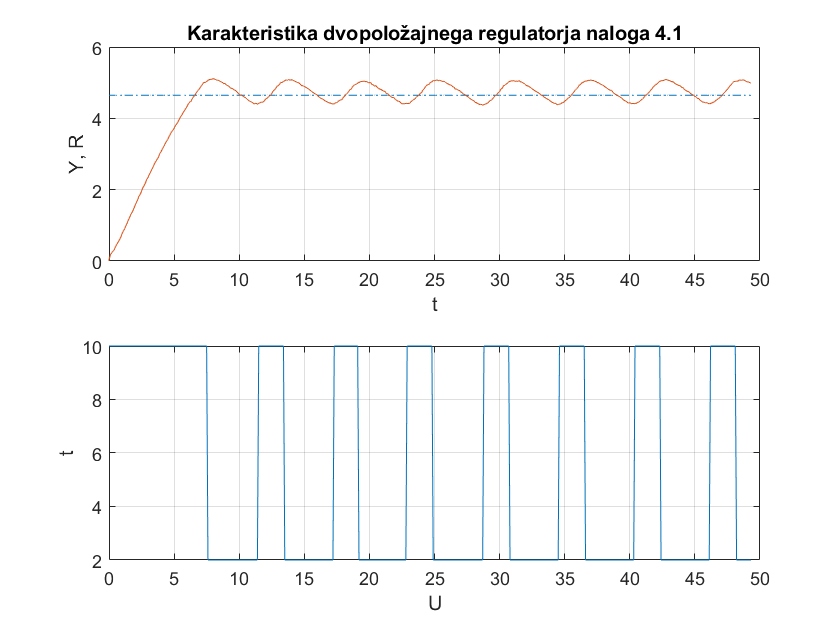

tsim = 50;
t2 = 25;
t_motnja = 0;
U_motnja = 0;
U2 = 4.648;
epsilon = 0.3;
eps1 = epsilon/2;
eps2 = -eps1;
Out_ON = 10;
Out_OFF = 2;
UDT = 5;
YDT = 4.648;

out41 = sim('regonoff2');
a = length(U);
b = length(Y);
c = a-b;
U = U(1:end-c,:);
R = R(1:end-c,:);
t_sim = t_sim(1:end-c,:);

figure;
subplot(2,1,1);
plot(t_sim, R,'-.', t_sim, Y);
xlabel('t'); ylabel('Y, R'); title('Karakteristika dvopoložajnega regulatorja naloga 4.1');
grid on
subplot(2,1,2);
plot(t_sim, U);
xlabel('U'); ylabel('t');
grid on

Pri tej nalogi smo pa izklopili vse dodatne stopnice in ohranili le osnovno referenco. (motnja = 0). Spreminjali smo le vrednost epsilon, kar se je poznalo na krajši periodi. Če bolj pozorno pogeldamo vidimo da se spremeni tudi amplituda - z manjšanjem epsilona upada amplituda ter perioda! Perioda se spremeni za cca. 20%, amplituda pa za 2% in to pri pol manjšem epsilonu.

## Naloga 4.2

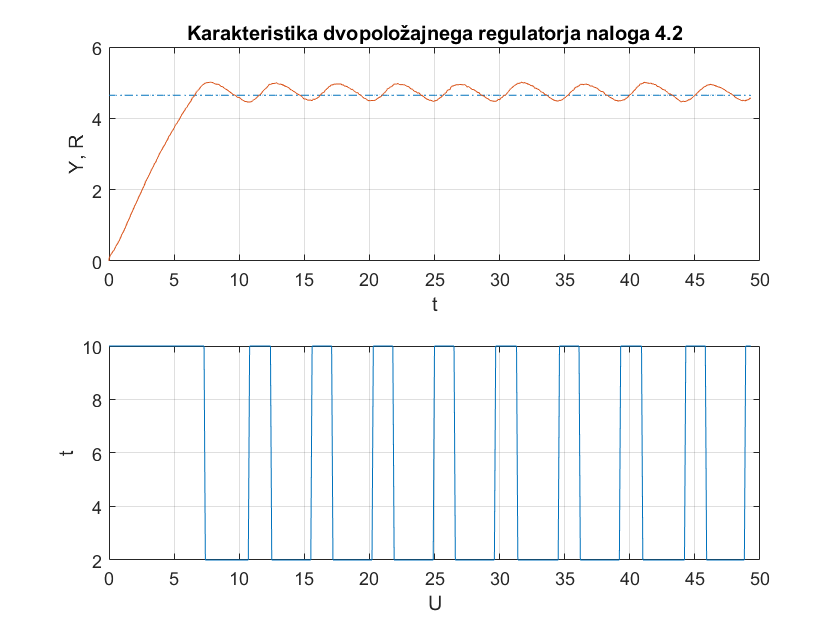

tsim = 50;
t2 = 25;
t_motnja = 0;
U_motnja = 0;
U2 = 4.648;
epsilon = 0.15;
eps1 = epsilon/2;
eps2 = -eps1;
Out_ON = 10;
Out_OFF = 2;
UDT = 5;
YDT = 4.648;

out42 = sim('regonoff2');
a = length(U);
b = length(Y);
c = a-b;
U = U(1:end-c,:);
R = R(1:end-c,:);
t_sim = t_sim(1:end-c,:);

figure;
subplot(2,1,1);
plot(t_sim, R,'-.', t_sim, Y);
xlabel('t'); ylabel('Y, R'); title('Karakteristika dvopoložajnega regulatorja naloga 4.2');
grid on
subplot(2,1,2);
plot(t_sim, U);
xlabel('U'); ylabel('t');
grid on

Enako kot pri prejšni nalogi smo pa izklopili vse dodatne stopnice in ohranili le osnovno referenco. (motnja = 0). Spreminjali smo le vrednost epsilon, kar se je poznalo na krajši periodi. Če bolj pozorno pogeldamo vidimo da se spremeni tudi amplituda - z manjšanjem epsilona upada amplituda ter perioda!

## Naloga 5

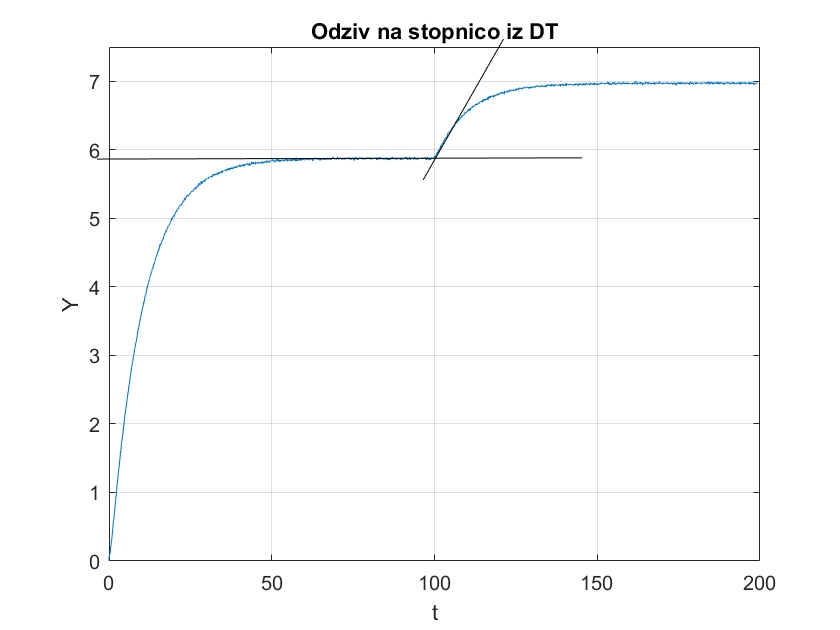

tsim = 200;
t1 = 0;
t2 = 100;
UDT = 5;
YDT = 4.648;
out5 = sim('Odziv');

a = length(Y);
b = length(t_sim);
c = abs(a-b);
t_sim = t_sim(1:end-c,:);

figure;
plot(t_sim, Y);
xlabel('t'); ylabel('Y');title('Odziv na stopnico iz DT')
grid on;

xlim([0 200])
ylim([0.00 7.500])
annotation('line',[0.1154 0.6928],[0.7475 0.7495])
annotation('line',[0.5038 0.5994],[0.7146 0.9381])

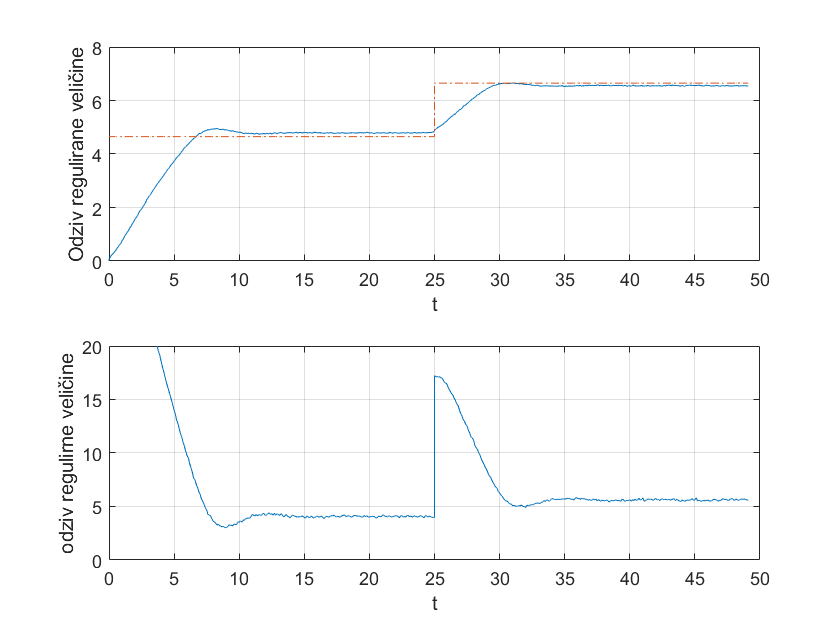


tsim = 50;
t1 = 0;
t2 = 25;
dU = 2;
dY = 6.943 - 5.876;
Ks = dY/dU;
Tza = 4;
Tiz = 20;
Kp = (0.7*Tiz)/(Ks*Tza);

figure;
out8 = sim('regp5');

a = length(Y_regulirana);
b = length(t_sim);
c = abs(a-b);
t_sim = t_sim(1:end-c,:);
R_referenca = R_referenca(1:end-c,:);
U_regulirna = U_regulirna(1:end-c,:);

subplot(2,1,1);
plot(t_sim, Y_regulirana, t_sim, R_referenca, '-.')
xlim([0 50]); xlabel('t');
ylim([0 8]); ylabel('Odziv regulirane veličine');
grid on

subplot(2,1,2);
plot(t_sim, U_regulirna)
xlim([0 50]); xlabel('t');
ylim([0 20]); ylabel('odziv regulirne veličine');
grid on

Najprej shemo v simulinku s katero bomo lahko dobili značilnosti sistema. Torej vzbujamo naš sistem s stopnico z referenčno vrednostjo v delovni točki, ter dodatno stopnico z amlitudo 1. To naredimo zato, da lahko odčitamo parametre regulatorja - Tza, Tiz s katerimi lahko s pomočjo tabele in CHR parametrov izračunamo Kp za P regulator (izberemo lahko parametre za aperiodični odziv z najkrajši Tum - tukaj dobimo manjše ojačanj kot pri drugi metodi - posledično bolj stabilno in počasnejši odziv brez prenihaja, jaz sem uporabil faktor 0.7 - najkrajši Tum z 20% prenihajem, kar nam da večje ojačanje in hitrejši vendar malo manj stabilen odziv na vhodne signale (nam tudi da boljši rezultat kot pri drugem z aperiodičnim odzivu)), nato pa naredimo po navodilih shemo za P regulator, ki skrbi zato da naš izhod v ustaljenem stanju sli referenci ki jo imamo na vhodu - jo merimo. Po teoriji bi morali dobiti na izhodu enako vrednost kot je referenčna, vendar imamo tukaj napako, katere vzroka ne poznam.

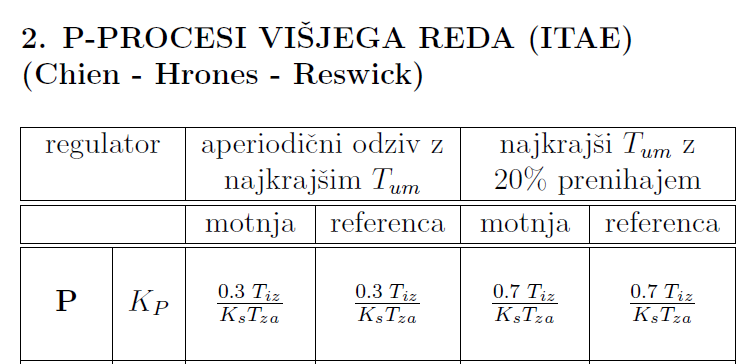

## Naloga6

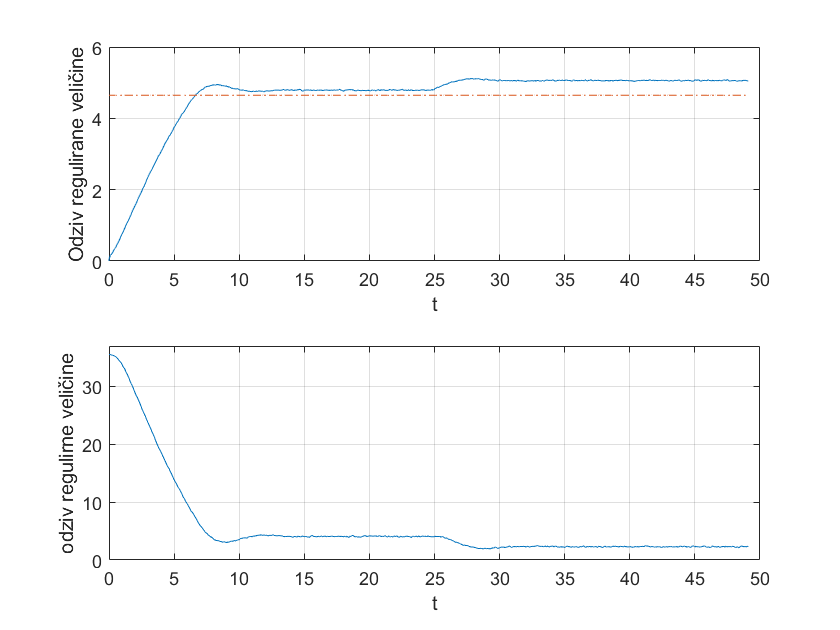

Kp = (0.3*Tiz)/(Ks*Tza);
motnja = 2;

figure;
out9 = sim('regp6');

a = length(Y_regulirana);
b = length(t_sim);
c = abs(a-b);
t_sim = t_sim(1:end-c,:);

R_referenca = R_referenca(1:end-c,:);
U_regulirna = U_regulirna(1:end-c,:);

subplot(2,1,1);
plot(t_sim, Y_regulirana, t_sim, R_referenca, '-.')
xlim([0 50]); xlabel('t');
ylim([0 6]); ylabel('Odziv regulirane veličine');
grid on

subplot(2,1,2);
plot(t_sim, U_regulirna)
xlim([0 50]); xlabel('t');
ylim([0 37]); ylabel('odziv regulirne veličine');
grid on

Naloga 6 je spet izpeljanka oz. nadrgradnja n 5. naloge, kjer moramo odpraviti napako tudi, ko je naš sistem izven delovne točke zaradi motnje, vendar kot vidimo, nam tudi to ti popolnoma uspelo ... Torej uporabimo faktor 0.7 - najkrajši Tum z 20% prenihajem, kar nam da večje ojačanje in hitrejši vendar malo manj stabilen odziv na vhodne signale.

Za laboratorijsko vajo sem porabil nekaj manj kot 8 ur efektivnega dela.

Lp.

Tadej